load('repBF0a8.mat');

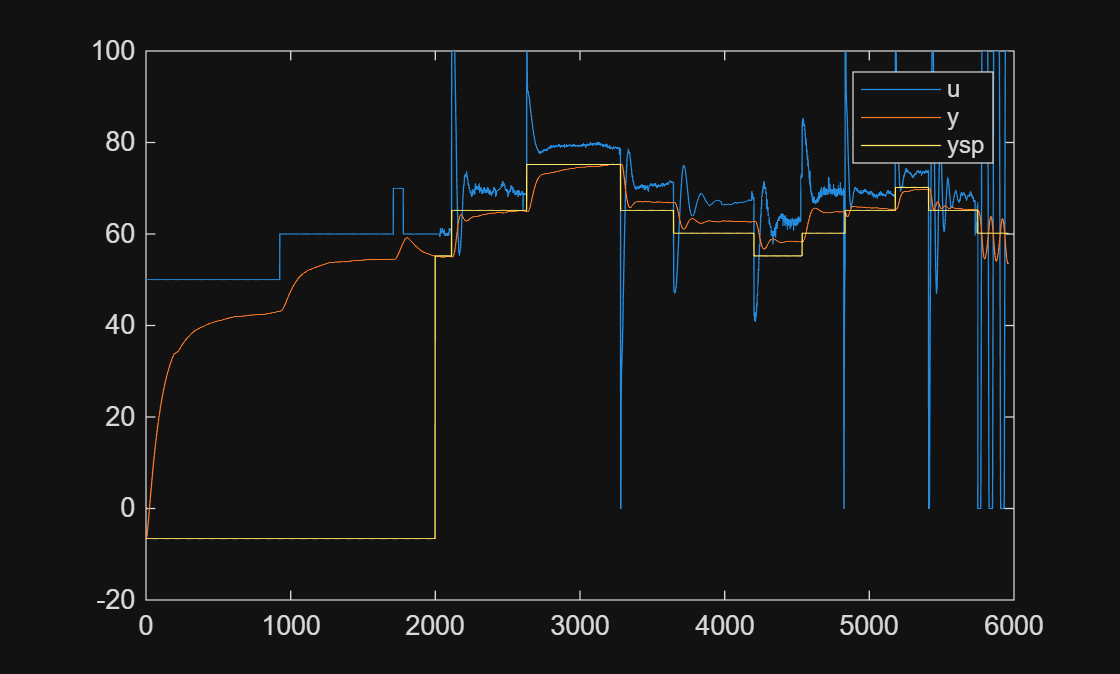

clf;
plot(t,u,t,y,t,ysp)
legend("u","y","ysp") % y c'est le reponse reel de l'installation

%ysp c'est la consigne
%u c'est lentrée de lactionneur jcrois



a=diff(ysp);% ca fait chaque point- le point d'avant,
ydif=a(a~=0);% je trouve toutes les differences differentes de 0
xdif=find(a~=0);% je trouve leur emplacement dans le temps(zehma grace a leur indice)

xstart=xdif(2)

xstart = 2113

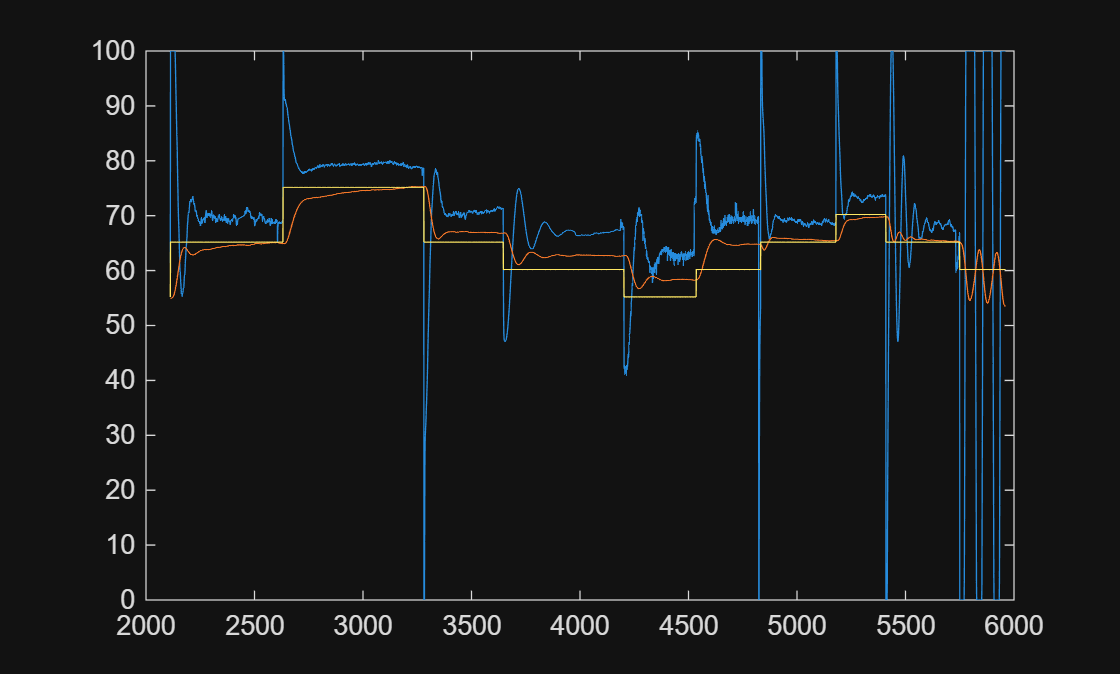


t1=t(xstart:t(end));
u1=u(xstart:t(end));
y1=y(xstart:t(end));
ysp1=ysp(xstart:t(end));
plot(t1,u1,t1,y1,t1,ysp1) %ici je regarde juste pour voir ce qui m'interresse, jai enlevé le temps de chauffe mais mhm on utilise pas apres



a1=diff(ysp1);% c'est comme au dessus mais juste sans le temps de chauffe
ydif1=a1(a1~=0)

ydif1 =     10
    10
   -10
    -5
    -5
     5
     5
     5
    -5
    -5


xdif1=find(a1~=0)

xdif1 =            1
         520
        1169
        1535
        2091
        2424
        2721
        3068
        3298
        3638


clf;
b1i=xdif(2) %je commence quand

b1i = 2113

b1f=xdif(3) %je termine quand

b1f = 2632

tessai1=b1i:b1f; %temps de l'essai
yessai1=y(tessai1); % je prends les points qui m'interesse
yessai1=yessai1-yessai1(1); %pour commencer ma réponse a 0 je la baisse de sa premiere valeur

yessai1=yessai1/mean(yessai1(end-10,end));% ma reponse pour quelle soit indicielle je divise par les 10 derniers points
                                            % EN PLUS LA MOYENNE CA REMET
                                            % MON TRUC A LENDROIT PAR
                                            % EXEMPLE SI JAVAIS UN ECHELON
                                            % DE -10
tessai10=tessai1-b1i; % je ramene le temps à 0
%plot(tessai10,yessai1)

clf;
b2i=xdif(3)

b2i = 2632

b2f=xdif(4)

b2f = 3281

tessai2=b2i:b2f;
yessai2=y(tessai2);
yessai2=yessai2-yessai2(1);
yessai2=yessai2/mean(yessai2(end-10,end));

tessai20=tessai2-b2i;
%plot(tessai20,yessai2)

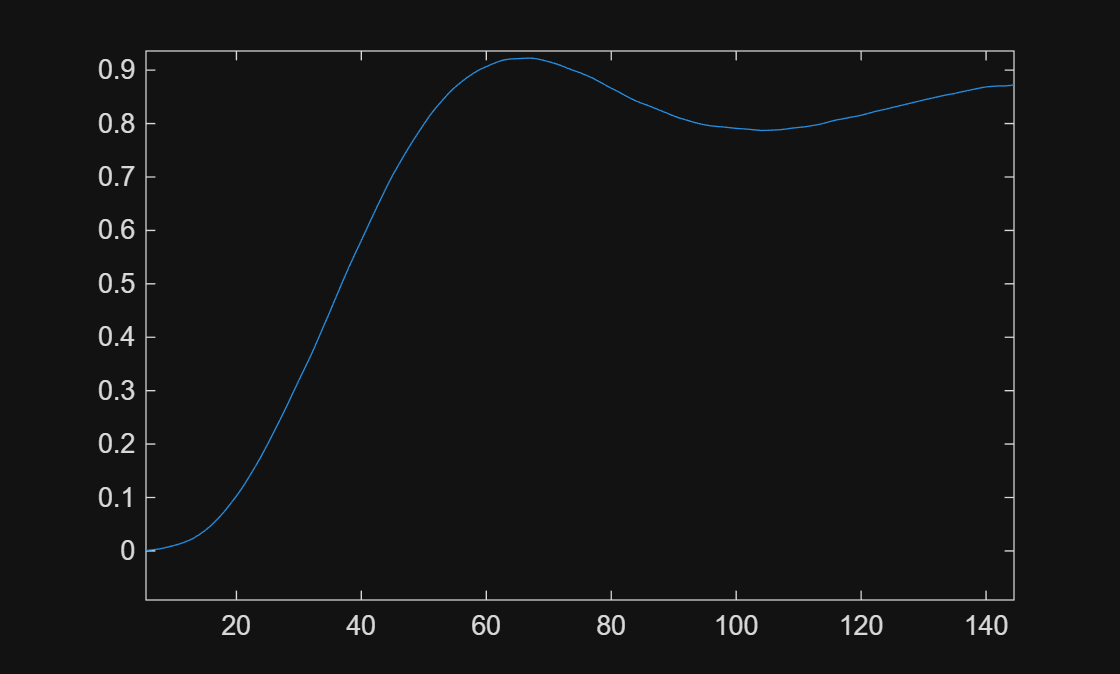

% sans boucle 
clf;
%hold on

% ESSAI 1
b1i = xdif(1);
b1f = xdif(2);
tessai1 = b1i:b1f;
yessai1 = y(tessai1);
yessai1 = yessai1 - yessai1(1);
yessai1 = yessai1 / mean(yessai1(end-10:end));
tessai10 = tessai1 - b1i;
%plot(tessai10, yessai1)

% ESSAI 2
b2i = xdif(2);
b2f = xdif(3);
tessai2 = b2i:b2f;
yessai2 = y(tessai2);
yessai2 = yessai2 - yessai2(1);
yessai2 = yessai2 / mean(yessai2(end-10:end));
tessai20 = tessai2 - b2i;
plot(tessai20, yessai2) %OK 1

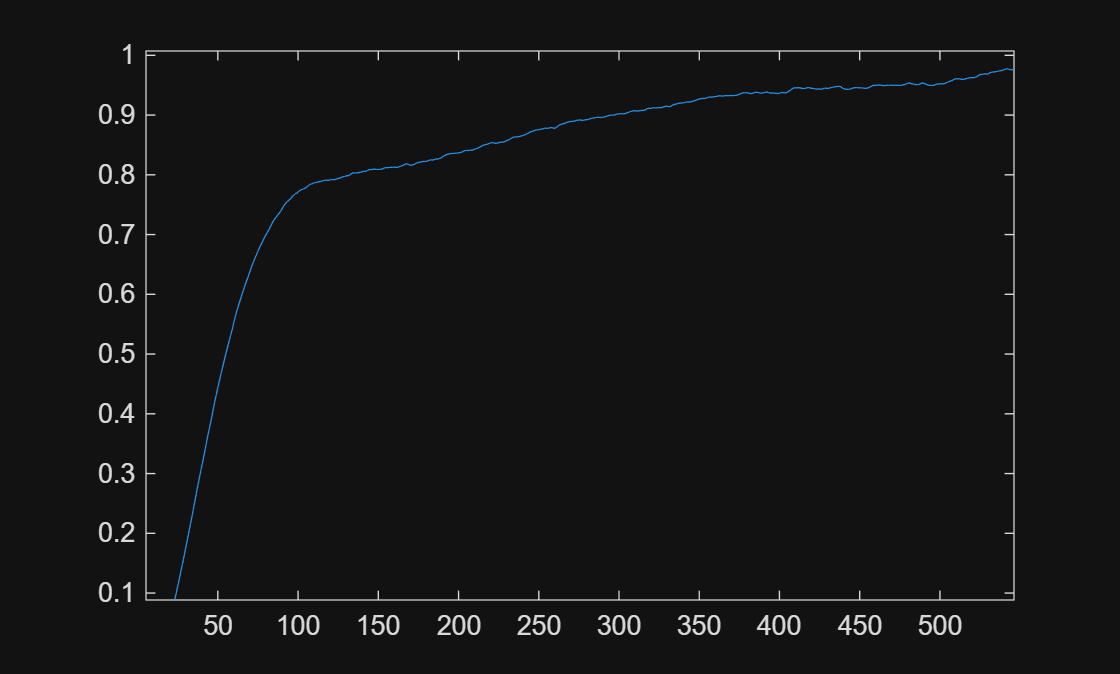


% ESSAI 3
b3i = xdif(3);
b3f = xdif(4);
tessai3 = b3i:b3f;
yessai3 = y(tessai3);
yessai3 = yessai3 - yessai3(1);
yessai3 = yessai3 / mean(yessai3(end-10:end));
tessai30 = tessai3 - b3i;
plot(tessai30, yessai3)%OK 2 BEST PID

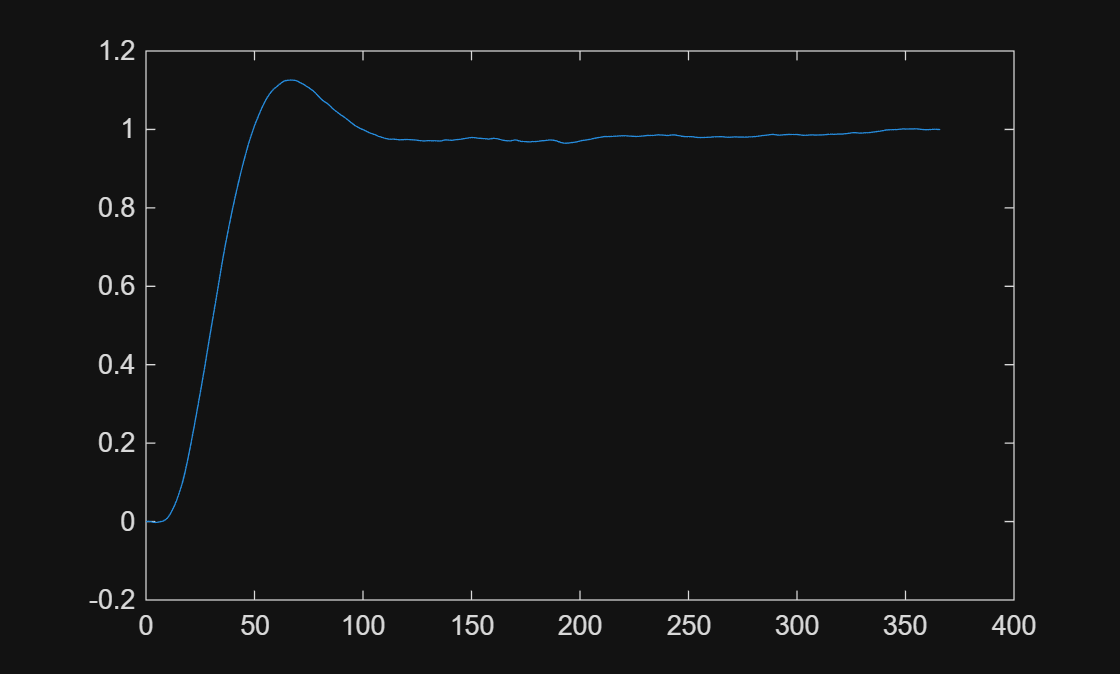


% ESSAI 4
b4i = xdif(4);
b4f = xdif(5);
tessai4 = b4i:b4f;
yessai4 = y(tessai4);
yessai4 = yessai4 - yessai4(1);
yessai4 = yessai4 / mean(yessai4(end-10:end));
tessai40 = tessai4 - b4i;
plot(tessai40, yessai4) %OK 3 BEST PID

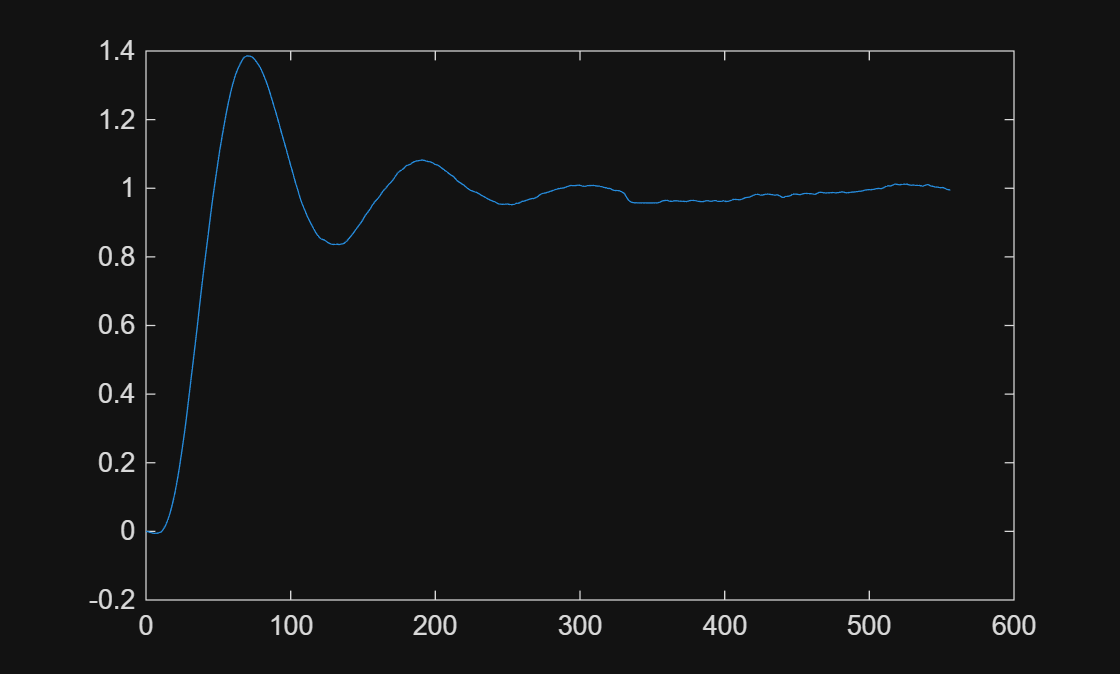



% ESSAI 5
b5i = xdif(5);
b5f = xdif(6);
tessai5 = b5i:b5f;
yessai5 = y(tessai5);
yessai5 = yessai5 - yessai5(1);
yessai5 = yessai5 / mean(yessai5(end-10:end));
tessai50 = tessai5 - b5i;
%plot(tessai50, yessai5) 

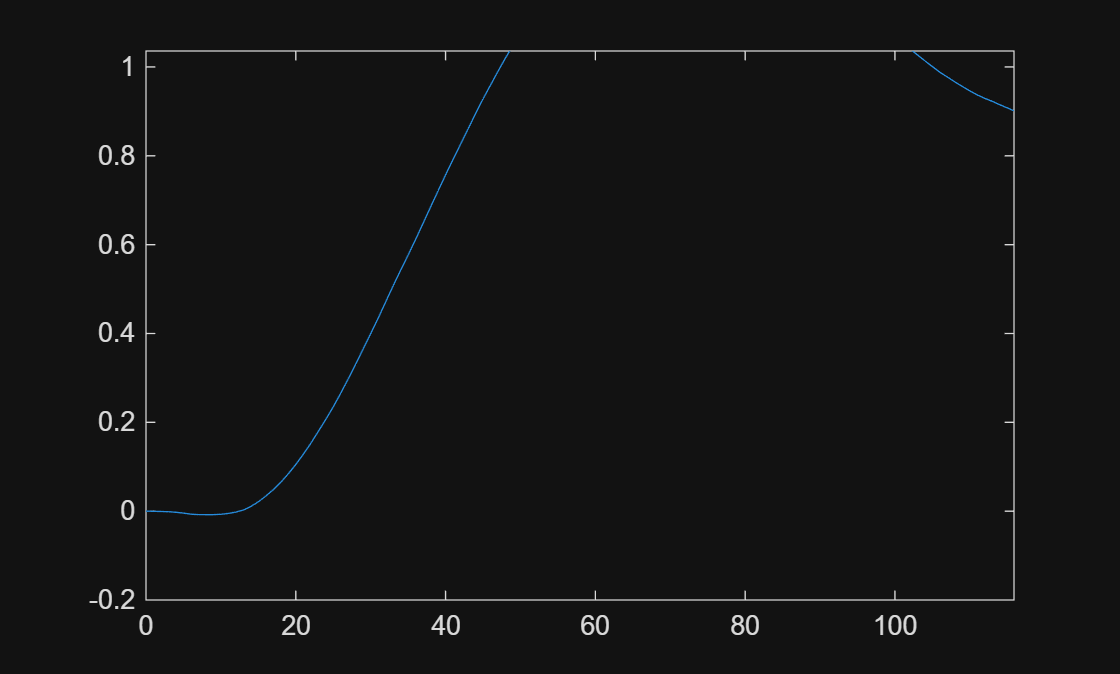


% ESSAI 6
b6i = xdif(6);
b6f = xdif(7);
tessai6 = b6i:b6f;
yessai6 = y(tessai6);
yessai6 = yessai6 - yessai6(1);
yessai6 = yessai6 / mean(yessai6(end-10:end));
tessai60 = tessai6 - b6i;
plot(tessai60, yessai6) %OK 4

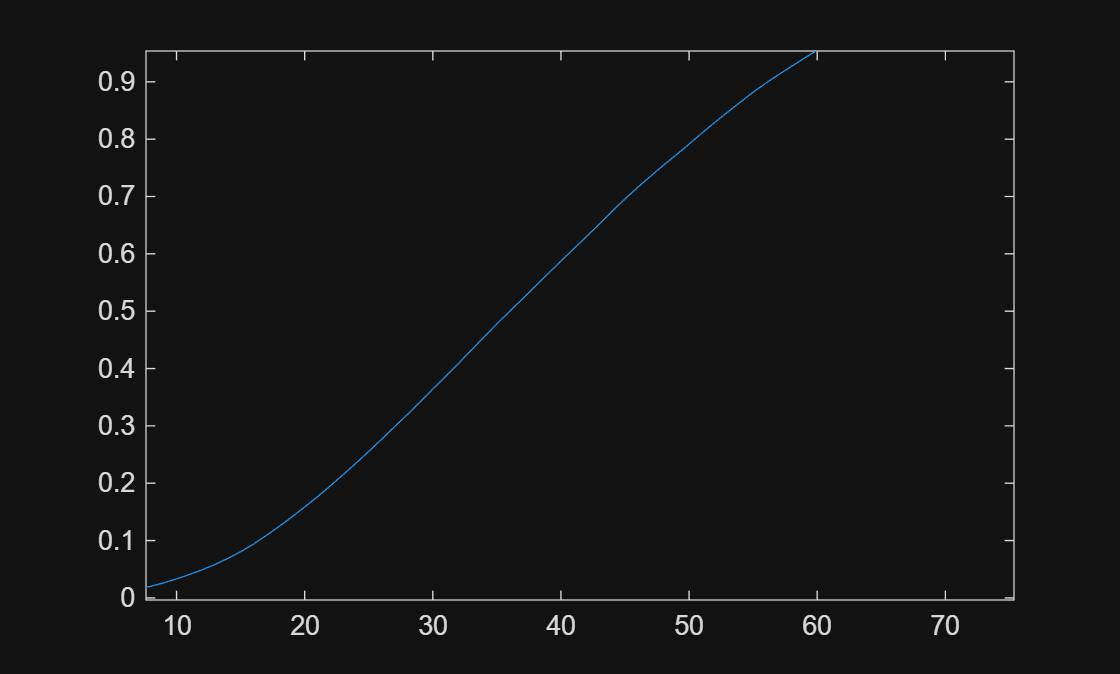


% ESSAI 7
b7i = xdif(7);
b7f = xdif(8);
tessai7 = b7i:b7f;
yessai7 = y(tessai7);
yessai7 = yessai7 - yessai7(1);
yessai7 = yessai7 / mean(yessai7(end-10:end));
tessai70 = tessai7 - b7i;
plot(tessai70, yessai7)%OK 5

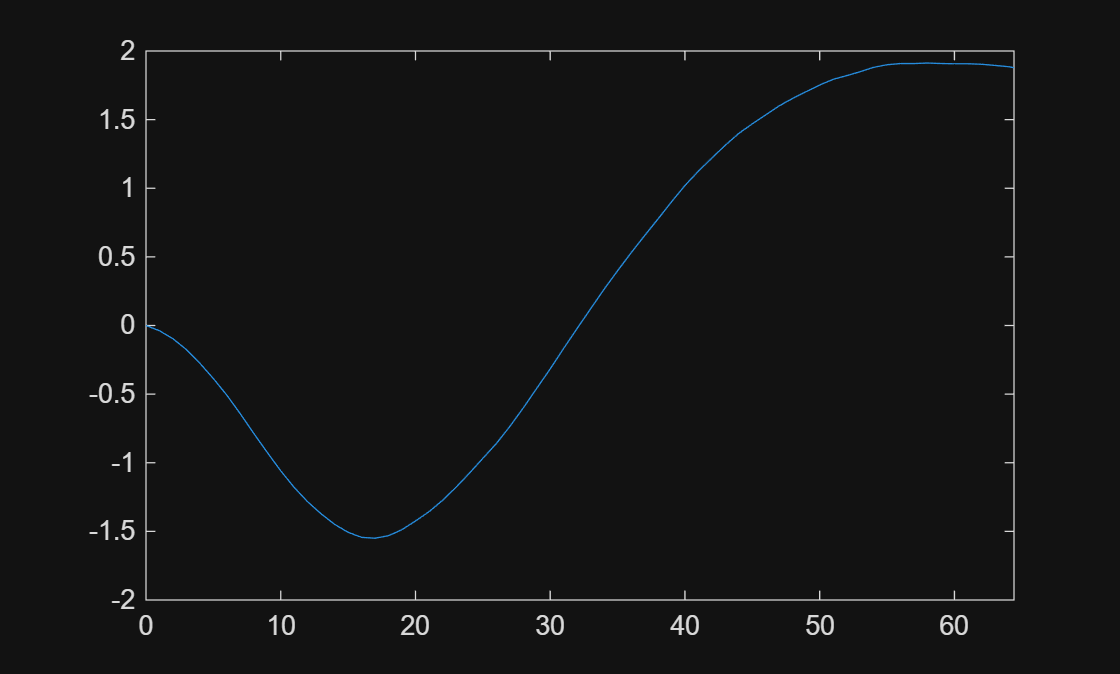


% ESSAI 8
b8i = xdif(8);
b8f = xdif(9);
tessai8 = b8i:b8f;
yessai8 = y(tessai8);
yessai8 = yessai8 - yessai8(1);
yessai8 = yessai8 / mean(yessai8(end-10:end));
tessai80 = tessai8 - b8i;
plot(tessai80, yessai8)

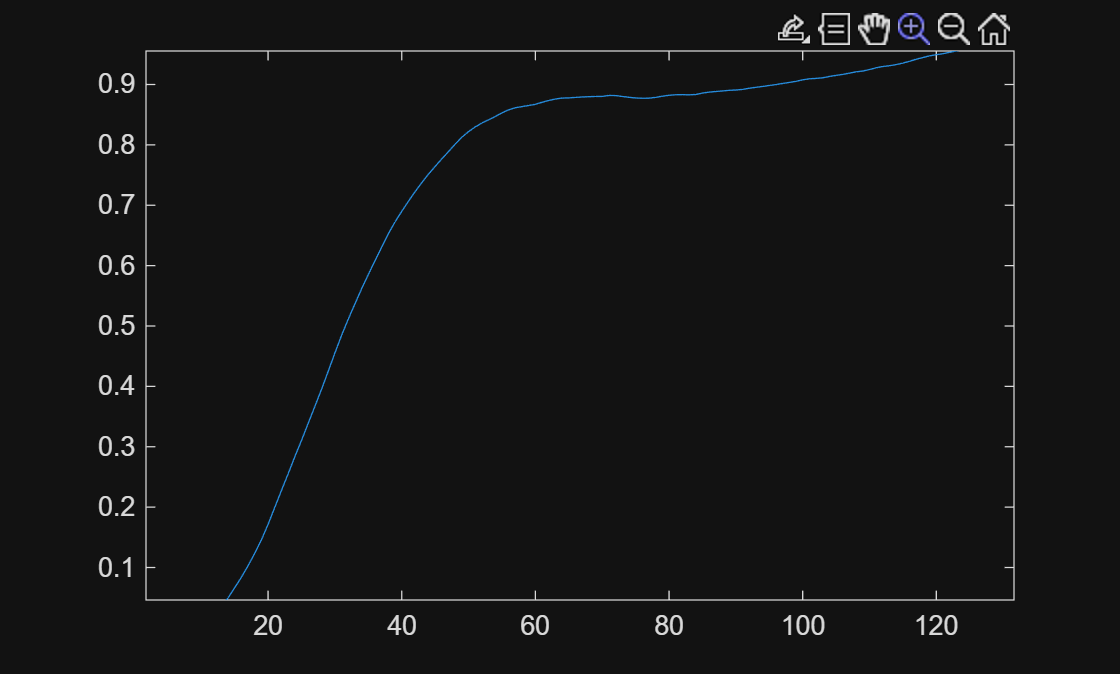


% ESSAI 9
b9i = xdif(9);
b9f = xdif(10);
tessai9 = b9i:b9f;
yessai9 = y(tessai9);
yessai9 = yessai9 - yessai9(1);
yessai9 = yessai9 / mean(yessai9(end-10:end));
tessai90 = tessai9 - b9i;
6plot(tessai90, yessai9) %OK 6

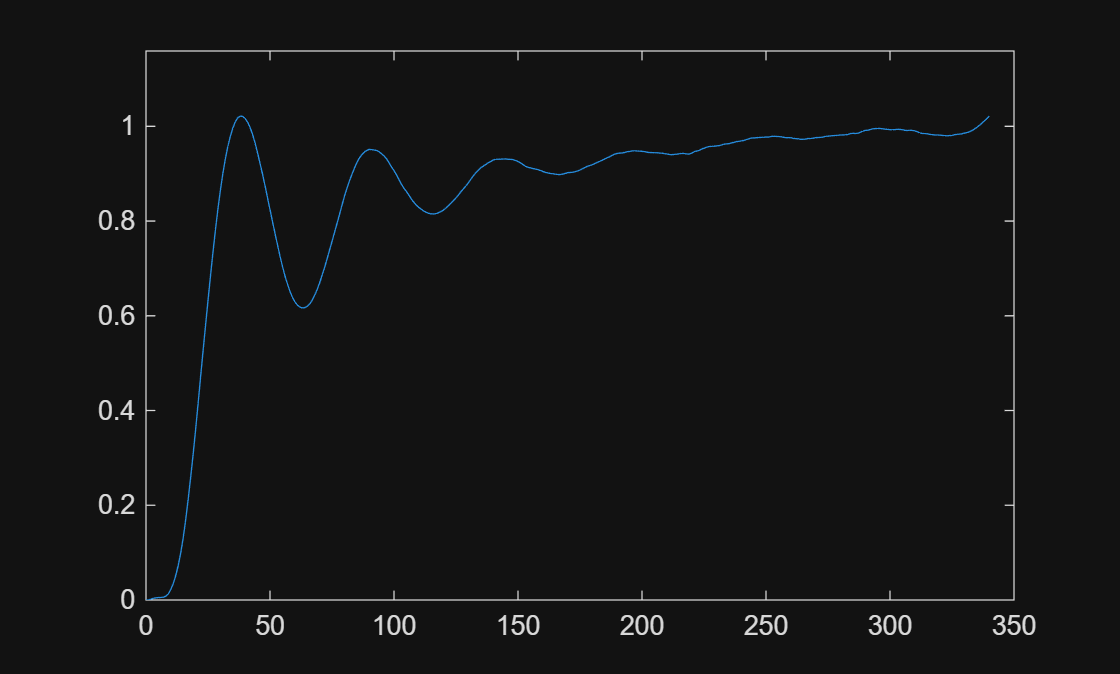


% ESSAI 10
b10i = xdif(10);
b10f = xdif(11);
tessai10 = b10i:b10f;
yessai10 = y(tessai10);
yessai10 = yessai10 - yessai10(1);
yessai10 = yessai10 / mean(yessai10(end-10:end));
tessai100 = tessai10 - b10i;
plot(tessai100, yessai10)%OK 7

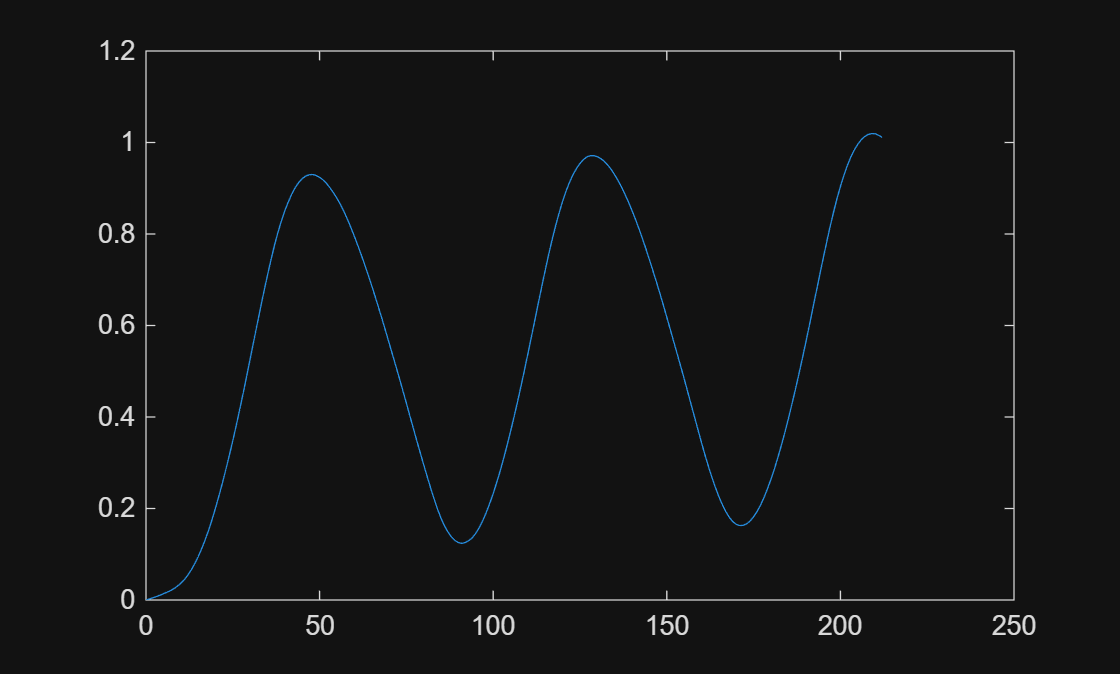

% ESSAI 11
b11i = xdif(11);
b11f = t(end);
tessai11 = b11i:b11f;
yessai11 = y(tessai11);
yessai11 = yessai11 - yessai11(1);
yessai11 = yessai11 / mean(yessai11(end-10:end));
tessai110 = tessai11 - b11i;
plot(tessai110, yessai11)%OK 8  

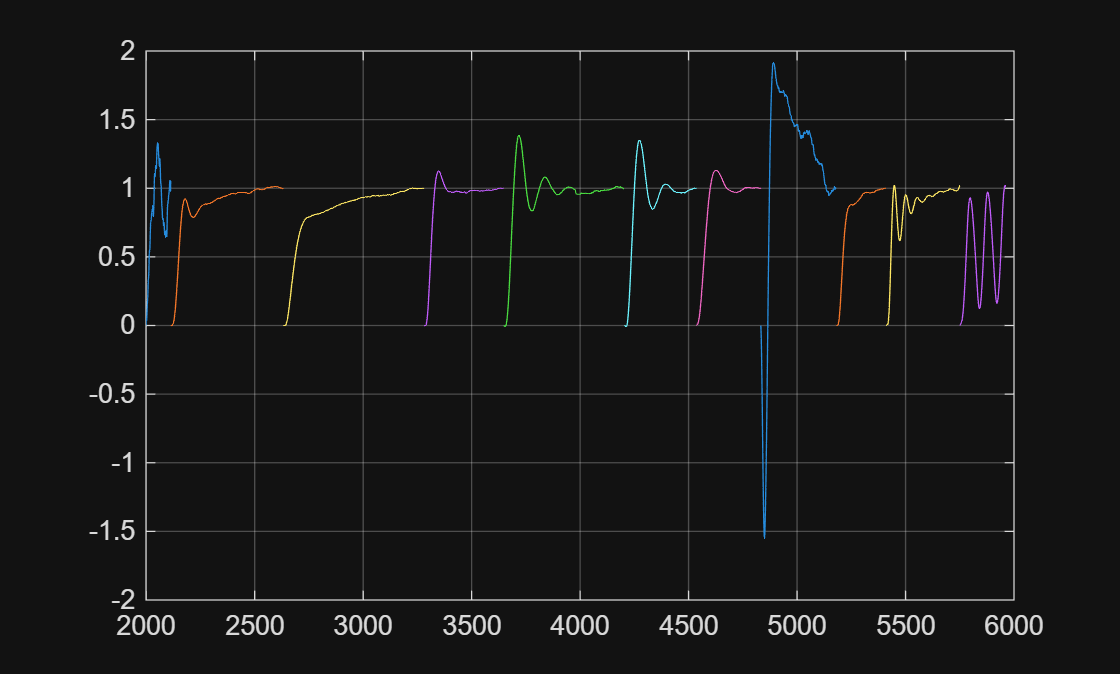


plot( ...
tessai1,yessai1, ...
tessai2,yessai2, ...
tessai3,yessai3, ...
tessai4,yessai4, ...
tessai5,yessai5, ...
tessai6,yessai6, ...
tessai7,yessai7, ...
tessai8,yessai8, ...
tessai9,yessai9, ...
tessai10,yessai10, ...
tessai11, yessai11)
grid on



% ESSAI 12
%b12i = xdif(12);
%b12f = xdif(13);
%tessai12 = b12i:b12f;
%yessai12 = y(tessai12);
%yessai12 = yessai12 - yessai12(1);
%yessai12 = yessai12 / mean(yessai12(end-10:end));
%tessai120 = tessai12 - b12i;
%plot(tessai120, yessai12)


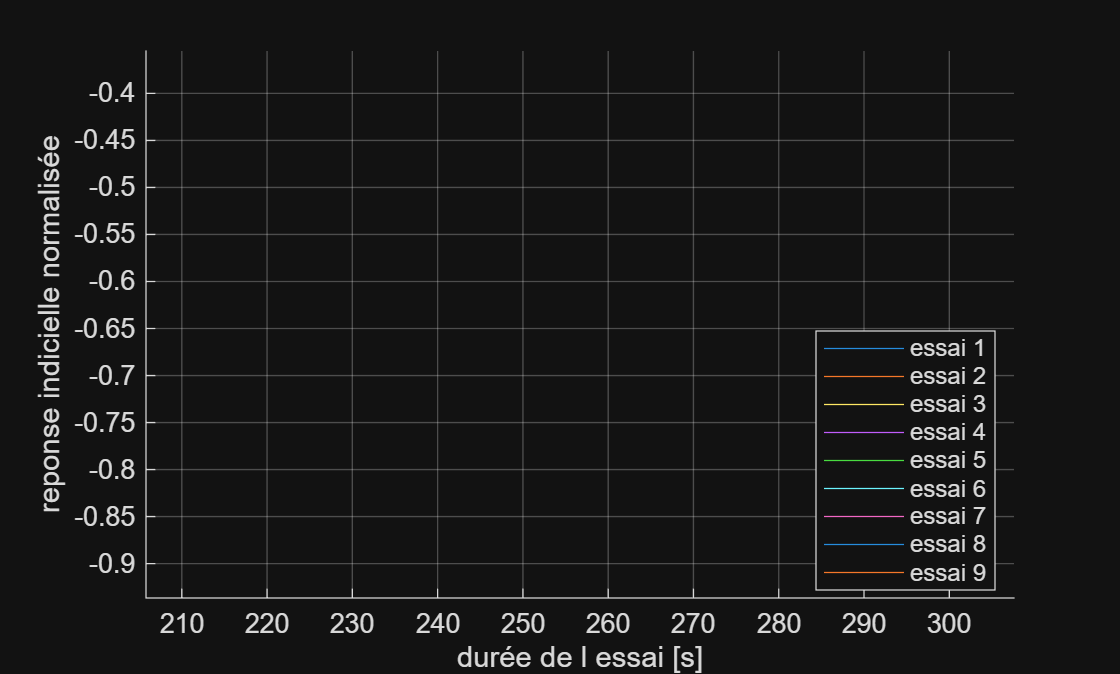

%avec boucle
clf; hold on; grid on

N = 9;                 % nombre d'essais
for k = 1:N
    bi = xdif(k);      % début
    bf = xdif(k+1);    % fin
    
    idx = bi:bf;
    yk = y(idx);

    % offset initial
    y0 = yk(1);
    yk = yk - y0;

    % normalisation (plus robuste que mean sur tout)
    yinf = mean(yk(max(1,end-10):end));   % moyenne des 10 derniers points
    yk = yk / yinf;

    t0 = idx - bi;     % temps relatif (en indices)
    plot(t0, yk);
end

legend(compose("essai %d", 1:N), 'Location','best')
xlabel('durée de l essai [s]')
ylabel('reponse indicielle normalisée')